## DC motor modeling

Based on : [https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling](https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling)

% motor params
J = 0.01        % kg*m^2

J = 0.0100

b = 0.10        % N*m*s

b = 0.1000

K = 0.01        % V/rad/s

K = 0.0100

R = 1           % Ohm

R = 1

L = 0.5         % H

L = 0.5000

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




% transfer function between speed and voltage
% P_omega = omega (s) / V (s)
P_omega = K / ( (J*s + b)*(L*s + R) + K^2 )

P_omega =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.



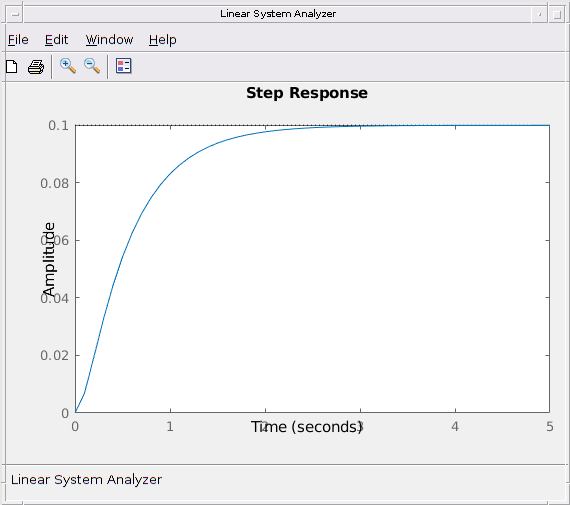

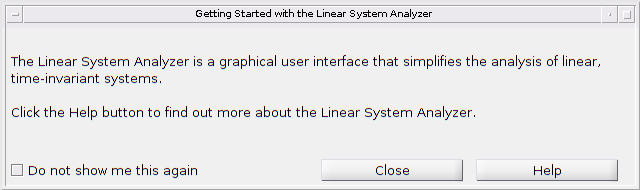

linearSystemAnalyzer('step', P_omega, 0:0.1:5);

# Get empiric data (speed control)

data = csvread("pos_vel_test1.csv", 1, 0);

time = data(:,1);
voltage = data(:,2);
omega = data(:,3);

Ts = mean(diff(time))

Ts = 0.0106

print speed data

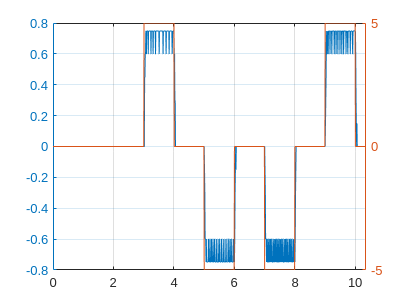

figure
yyaxis left
plot(time, omega)
hold on 
yyaxis right
plot(time, voltage)
grid on

estimate model

dc_data = iddata(omega, voltage, Ts);
tf_model = tfest(dc_data, 1, 0, 0)       % first order + integrator

tf_model =
  From input "u1" to output "y1":
    5.742
  ---------
  s + 39.76
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "dc_data".
Fit to estimation data: 90.95%                      
FPE: 0.001619, MSE: 0.001609                        
 
Model Properties


verify model against empiric data

t = 0:Ts:10.3500;
omega_model = lsim(tf_model, voltage, t)   % u,t define the input signal

omega_model =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


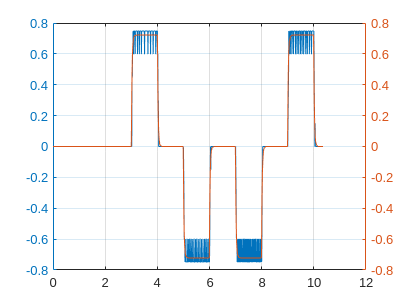


figure
yyaxis left
plot(time, omega)
hold on 
yyaxis right
plot(time, omega_model)
grid on

obtain PI coefficients

sys_d = c2d(tf_model, Ts)

sys_d =
  From input "u1" to output "y1":
   0.04956 z^-1
  ---------------
  1 - 0.6568 z^-1
 
Sample time: 0.010572 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties



pidTuner(sys_d)     % z =0.85, tr = 3.0s

# Get empiric data (position control)

data = csvread("pos_test3.csv", 1, 0);

time = data(:,1);
voltage = data(:,2);
theta = data(:,3);

Ts = mean(diff(time))

Ts = 0.0100

print speed data

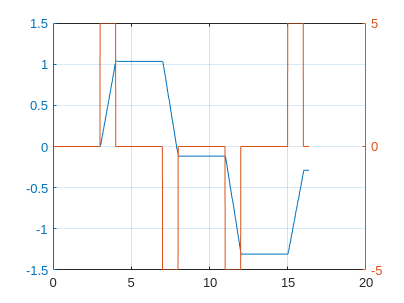

figure
yyaxis left
plot(time, theta)
hold on 
yyaxis right
plot(time, voltage)
grid on

estimate model

dc_data = iddata(theta, voltage, Ts);
tf_model = tfest(dc_data, 2, 0, 0)       % second order + integrator

tf_model =
  From input "u1" to output "y1":
           4.84
  ----------------------
  s^2 + 20.45 s + 0.2077
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "dc_data".
Fit to estimation data: 91.98%                      
FPE: 0.004038, MSE: 0.004014                        
 
Model Properties


verify model against empiric data

t = 0:Ts:10.35

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


theta_model = lsim(tf_model, voltage, t)   % u,t define the input signal

Error using DynamicSystem/lsim
When simulating the response to a specific input signal, the input data U must be a matrix with as many rows as samples in the time
vector T, and as many columns as input channels.


figure
yyaxis left
plot(time, theta)
hold on 
yyaxis right
plot(time, theta_model)
grid on

obtain PI coefficients

sys_d = c2d(tf_model, Ts)

pidTuner(sys_d, 'PID' )     % 

% kp = 2 ; ki = 3
%series = [ 8, 16, 6, 6, 4, 10, 4, 10, 6, 14, 8, 5, 9, 12, 16, 16, 10, 12, 16, 12, 10, 8, 10, 16, 16, 14, 4, 12, 12, 10, 12, 8, 9, 11, 8, 6, 10, 15, 14, 11, 13, 12, 8, 0, 13, 16, 4, 10, 4, 14, 12, 14, 10, 6, 14, 16, 8, 6, 8, 4, 8, 14, 10, 3, 6, 16, 8, 8, 7, 15, 20, 12, 6, 10, 12, 8, 14 ]

series = [ 0, -0, 1, 0, -0, -0, -1, 1, -1, 0, -1, -1, -1, -1, 1, 0, 1, 1, 1, 0, -0, -1, 0, -0, -1, -1, -0, -1, 0, -0, -1, 1, 1, -1, 0, -1, -1, 0, 0, -0, -0, -1, -0, 0, -1, -0, 1, 0, -0, -1, -1, -0, 0, -0, -1, -1, 0, -0, 0, -1, -0, -1, 0, 1, -1, -1, -0, 1, -1, -1 ]

data = csvread("2_10_0.5_.csv", 1, 0);

time = data(:,1);
target = data(:,2);
omega = data(:,3);

Ts = mean(diff(time))

figure
yyaxis left
plot(time, target)
hold on 
yyaxis right
plot(time, omega)
grid on